# Coin exchange model for relaxation process

clear all; clf;

## 非平衡から平衡への緩和：平均的挙動との比較

ここでは2つの系A，Bが熱エネルギーの交換によって平衡状態に緩和する過程を，コイン交換モデルで表現する．

このモデルではAとBの2人がコインを交換することを考える．

はじめAは青いコインを $N$ 枚，Bは赤いコインを $N$ 枚持っているものとし，青と赤のコインにはそれぞれ，エネルギーに見立てた得点 $+1,-1$ が割り当てられているものとする．

その後，Aの持っているコインとBの持っているコインを1枚ずつ無作為に選んで交換するという操作を繰り返す．

数値シミュレーションの結果から読み取れるように，ある程度時間が経つと (試行を繰り返すと)，A，B各々の合計得点 $E_{\mathrm{A}},E_{\mathrm{B}}$ (を規格化した値 $\eta_{\mathrm{A}}
=E_{\mathrm{A}}/N,
\eta_{\mathrm{B}}
=E_{\mathrm{B}}/N$) はゼロに緩和する．

これは A (またはB) の持つ赤と青のコインが同数となる状態に対応する．

しかしながら $\eta_{\mathrm{A}},
\eta_{\mathrm{B}}$ が平均値ゼロの周りにゆらいでいる様子も見て取れる．

($N$を大きくすると，このゆらぎは目立たなくなる．)

ここから緩和過程を平均挙動とゆらぎに分離して理解することが動機付けられる．

そこでまずは平均挙動に着目する．

このような平衡状態への緩和過程では，(平均的には) 合計得点 $E_{\mathrm{A}}$ は (したがって$\eta_{\mathrm{A}}$は) 時間とともに指数関数的に緩和することが理論的に知られている．

確かに $\eta_{\mathrm{A}}$ の時系列は指数関数を用いて良くフィットできる．

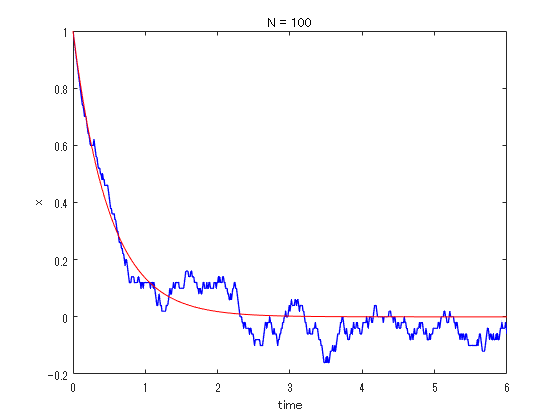

T = 6; %時間
N = 100; %コイン数

[tm, sm1] = coin_exchange(T, N);

## 平衡状態：平均的挙動とゆらぎを分離する

### 平衡状態のゆらぎ（平衡ゆらぎ）

次にゆらぎに着目する．

$\eta_{\mathrm{A}}$ の時系列から平均的な指数緩和を差し引けば，ゆらぎの時系列を取り出すことができる．

グラフに示すように，このゆらぎについての頻度分布は正規分布となっている．

また1試行における得点変化の頻度分布のグラフについて，1試行ごとの得点変化は

- 青いコインを渡して青いコインを受け取る場合　$\pm 0$

- 青いコインを渡して赤いコインを受け取る場合　$-2$

- 赤いコインを渡して青いコインを受け取る場合　$+2$

- 赤いコインを渡して赤いコインを受け取る場合　$\pm 0$

であり，それぞれが等確率で起こる．

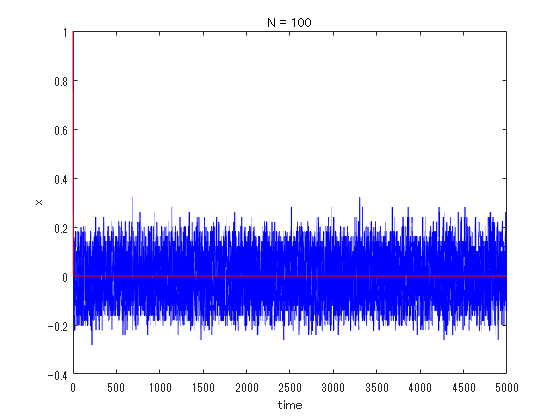

T = 5000; %時間
N = 100; %コイン数
[tm, sm1] = coin_exchange(T, N);

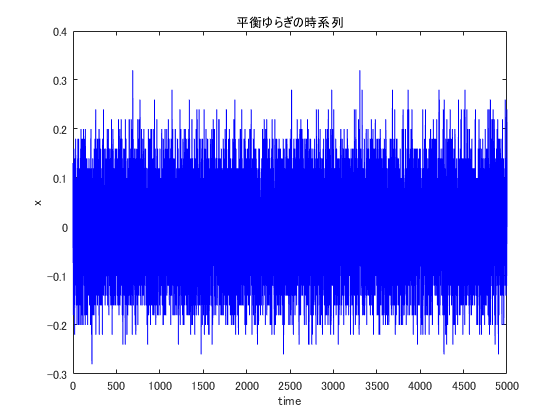


dv = sm1-exp(-2*tm);
plot(tm(20:end), dv(20:end), '-b', "LineWidth", 0.5);
xlabel('time')
ylabel('x')
title('平衡ゆらぎの時系列')

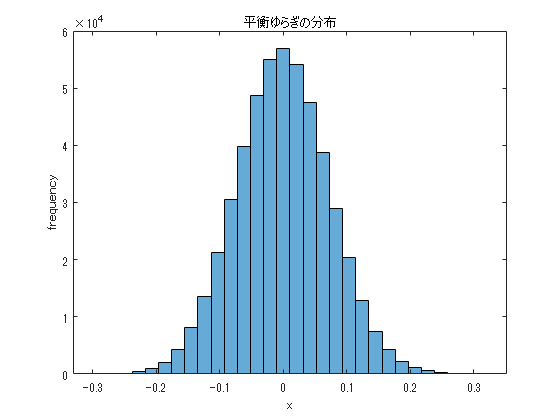


h1 = histogram(dv(20:end),30);
xlabel('x')
ylabel('frequency')
title('平衡ゆらぎの分布')


h1x = h1.BinEdges+0.5*h1.BinWidth;
h1x = h1x(1:end-1);
h1y = h1.Values;

### 平衡ゆらぎの分布：ガウス分布によるフィッティング

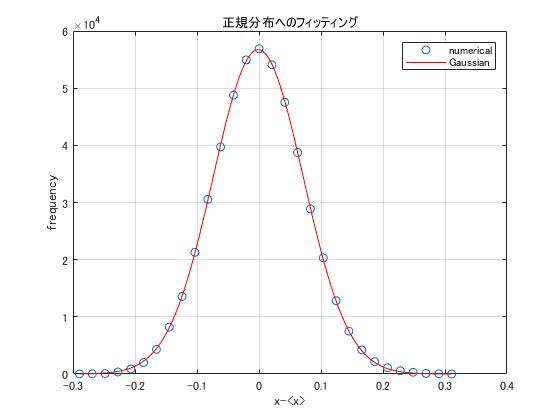

%% 近似:
[xData, yData] = prepareCurveData( h1x, h1y );

% 近似タイプとオプションを設定します。
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [22655 -0.0187 0.0486660050980374];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts );

% データの近似をプロットします。
figure( 'Name', '正規分布へのフィッティング' );
h = plot( fitresult, xData, yData, 'o' );
legend( h, 'numerical', 'Gaussian', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
xlabel( 'x-<x>', 'Interpreter', 'none' );
ylabel( 'frequency', 'Interpreter', 'none' );
title('正規分布へのフィッティング')
grid on

### １ステップあたりの $\eta$ の変化量


histogram(diff(sm1-exp(-2*tm)),[-0.025:0.01:0.025])
xlabel('乱数の値')
ylabel('frequency')
title('1step に入力される乱数の頻度分布')


## コイン交換を行い、描画する関数

function [tm, sm1] = coin_exchange(T, N)
Tn = T*N;
s01 =  N;
s02 = -N;

x1 = 0:1:Tn;

tm  = x1/N;
sm1 = 0*x1;
sm2 = 0*x1;

sm1(1) = s01/N;
sm2(1) = s02/N;

for j = 2:1:Tn+1
    if rand < (s01/N + 1)*0.5 
        ch1 = 1;
    else
        ch1 = -1;
    end
    if rand < (s02/N + 1)*0.5 
        ch2 = 1;
    else
        ch2 = -1;
    end
    s01 = s01 - ch1 + ch2;
    s02 = s02 + ch1 - ch2;

    sm1(j) = s01/N;
    sm2(j) = s02/N;
end
plot(tm, sm1, '-b', "LineWidth", 1)
hold on
plot(tm, exp(-2*tm), '-r', "LineWidth", 0.5)
xlabel('time')
ylabel('x')
title(['N = ', num2str(N)])
hold off
end